# ME 535 Assignment 3, Fall 2018 - Addendum

# Debabrata Auddya

**Question 4.3:**

**c.  Read the IGES file into Matlab**

**Name of igs file: Elephant.igs**

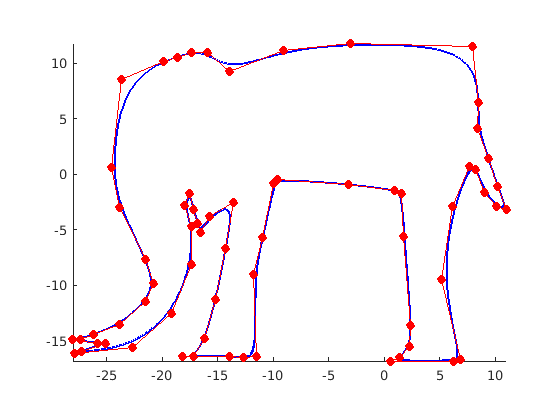

degree 3
weights
  Columns 1 through 24

     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1

  Columns 25 through 48

     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1

  Columns 49 through 67

     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1

control points...
  -18.6117   10.5753         0
  -19.8940   10.1746         0
  -23.6342    8.5717         0
  -24.5959    0.6372         0
  -23.8746   -2.9694         0
  -21.4702   -7.6980         0
  -20.8291   -9.8619         0
  -21.5504  -11.4648         0
  -23.8746  -13.5486         0
  -26.1988  -14.4302         0
  -27.4010  -14.8310         0
  -28.0422  -14.9111         0
  -25.8783  -15.2317         0
  -25.0768  -15.2317         0
  -27.3209  -15.9530         0
  -27.8819  -16.11

% read the igs file to matlab
clear;clf;
file_name = input('Pleas input the file name: ','s');
fp = fopen(file_name, 'r');
s = fscanf(fp,'%c',[82 inf]);s=s';
fclose(fp);

n=size(s);
j=0;
for i=1:n(1)-1
    temp = s(i,:);
    t = str2double(temp(6:8));
    % If t=126 indicate this line recorded a BS_curve
    if t == 126
        j = j+1;
        % find the bs_curve parameter segment number
        l = temp(13:16);
        % the following find BS_curve parameter segment
        for ii = i:n(1)-1
            temp1 = s(ii,:);
            % find BSCURVE parameter segment
            if strcmp(temp1(77:80),l) & str2double(temp1(1:3)) == t
                % parameter segment sign, in our example is '21P'
                temp2 = temp1(70:73);
                row1 = ii;
                for i2 = ii:n(1)-1
                    temp3 = s(i2,:);
                    % find all parameter lines in the same BSCURVE
                    if strcmp(temp3(70:73),temp2)
                        % record the last BS_curve parameter line
                        k = i2;
                    end
                end
                for i3=1:k-row1+1
                    bs(i3,:)=s(row1+i3-1,:);
                end
                %call bspline processing function
                hold on;
                bsp_curve(bs);
                clear bs
            end
        end
    elseif t==128 %  BS_surface
        j=j+1;
        l = temp(13:16);%bs_surface eparameter segment
        %  find bs_surface parameter
        for ii=i:n(1)-1
            temp1=s(ii,:);
           if strcmp(temp1(77:80),l) & str2double(temp1(1:3)) == t% find BSCURVE parameter segment
                % parameter segment example: 25p
                temp2 = temp1(70:73);
                row1=ii;
                for i2=ii:n(1)-1
                    temp3=s(i2,:);
                    % find all parameter lines in the same BSCURVE
                    if strcmp(temp3(70:73),temp2)
                        k=i2; %record the last BS_cruve parameter line
                    end
                end
                for i3=1:k-row1+1
                    bs(i3,:)=s(row1+i3-1,:);
                end
                %call bs drawing function
                hold on;
                bsp_surface(bs);
                view(-8,-42);
                clear bs
            end
        end
    end
    
end